# Longitudinal Vehicle - Main Script

This script uses `Vehicle1DDriveline_refsub` for the Longitudinal Vehicle block.

## Open Model and Run Simulation

mdl = "Vehicle1D_harness_model";
if not(bdIsLoaded(mdl))
  load_system(mdl)
end

% Load default parameters
Vehicle1D_harness_setup

set_param(mdl + "/Longitudinal Vehicle", ...
  "ReferencedSubsystem", "Vehicle1DDriveline_refsub")

## Vehicle Longitudinal Property

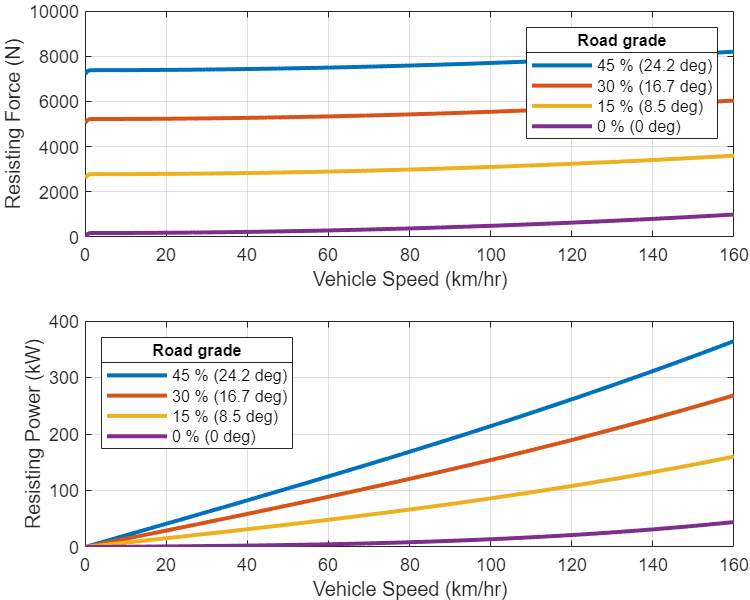

% Select subsystem
set_param(0, "CurrentSystem", mdl+"/Longitudinal Vehicle")

% Select block
set_param(gcs, "CurrentBlock", "Longitudinal Vehicle")

block_info = Vehicle1DUtility.getVehicle1DDrivelineBlockInfo(gcbh);

fig = Vehicle1DUtility.plotRoadLoad( ...
  "VehicleMass_kg", block_info.M_e_kg, ...
  "RoadLoadA_N", block_info.A_rl_N, ...
  "RoadLoadB_N_per_kph", block_info.B_rl_N_per_kph, ...
  "RoadLoadC_N_per_kph2", block_info.C_rl_N_per_kph2, ...
  "GravitationalAcceleration_m_per_s2", block_info.grav_m_per_s2, ...
  "VehicleSpeedVector_kph", linspace(0, 160, 200), ...
  "RoadGradeVector_pct", [45, 30, 15, 0] );
fig.Position(3:4) = [500 400];  % width height

% Set up external input signals
vehSigBuilder = Vehicle1D_InputSignalBuilder;
inputPatterns = [
  "Constant"
  "Coastdown"
  "Brake3"
  "RoadGrade3"
  "DriveAxle"
];
numSim = numel(inputPatterns);

% Create SimulationInput object for each simulation
%simIn(1:numSim) = Simulink.SimulationInput(mdl);  % error in R2022a.
simIn(1:numSim) = Simulink.SimulationInput(char(mdl));
for idx = 1 : numSim
  inpData = feval(inputPatterns(idx), vehSigBuilder);
  simIn(idx) = setVariable(simIn(idx), "vehicle_InputSignals", inpData.Signals);
  simIn(idx) = setVariable(simIn(idx), "vehicle_InputBus", inpData.Bus);
  simIn(idx) = setModelParameter(simIn(idx), "StopTime",num2str(inpData.Options.StopTime_s));
  switch inputPatterns(idx)
  case "Coastdown"
    simIn(idx) = setVariable(simIn(idx), "initial.vehicleSpeed_kph", ...
                  inpData.Options.Coastdown.InitialVehicleSpeed_kph);
  end
end

% Run simulations
simOut = sim(simIn, "UseFastRestart","on", "ShowProgress","on");

[11-Apr-2022 13:26:20] Running simulations...
[11-Apr-2022 13:26:22] Completed 1 of 5 simulation runs
[11-Apr-2022 13:26:22] Completed 2 of 5 simulation runs
[11-Apr-2022 13:26:22] Completed 3 of 5 simulation runs
[11-Apr-2022 13:26:23] Completed 4 of 5 simulation runs
[11-Apr-2022 13:26:24] Completed 5 of 5 simulation runs


## Simulation Results

Constant


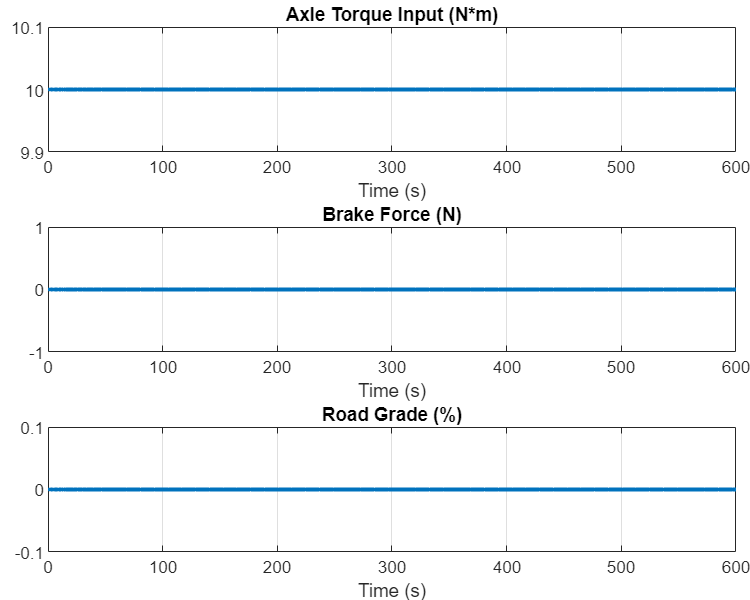

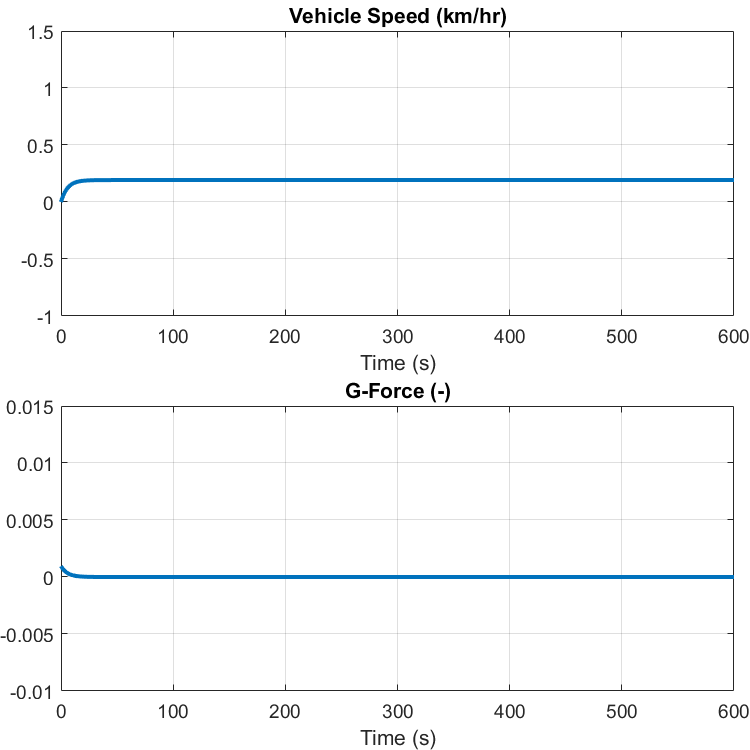

Coastdown


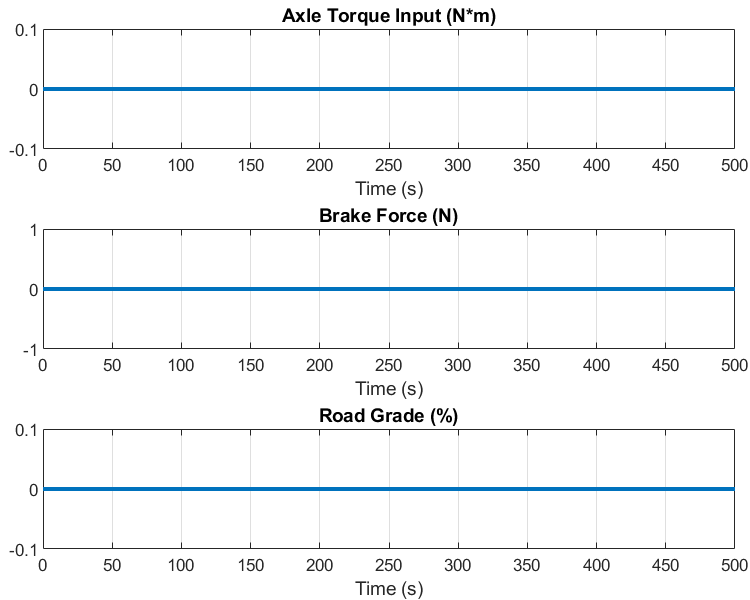

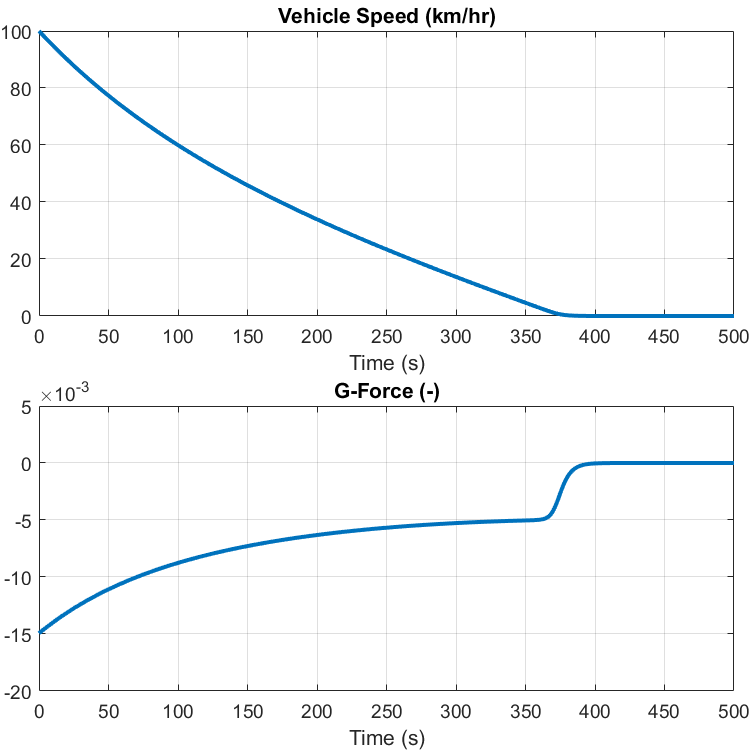

Brake3


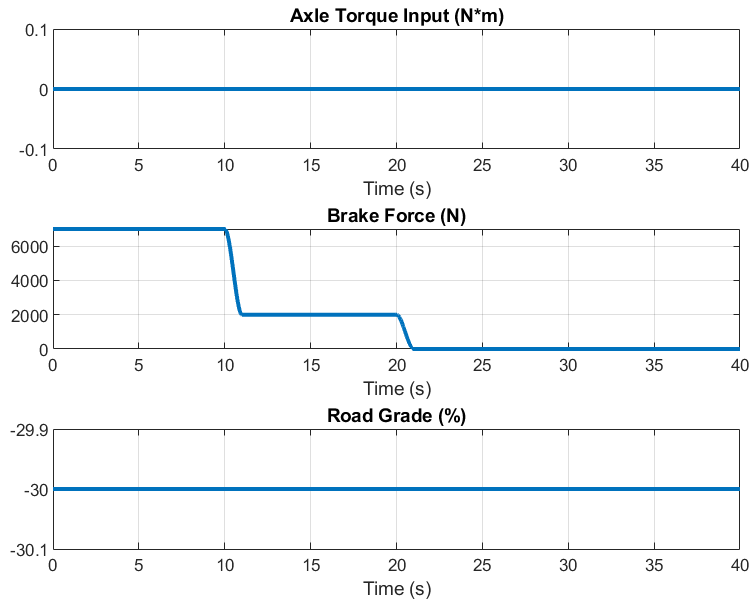

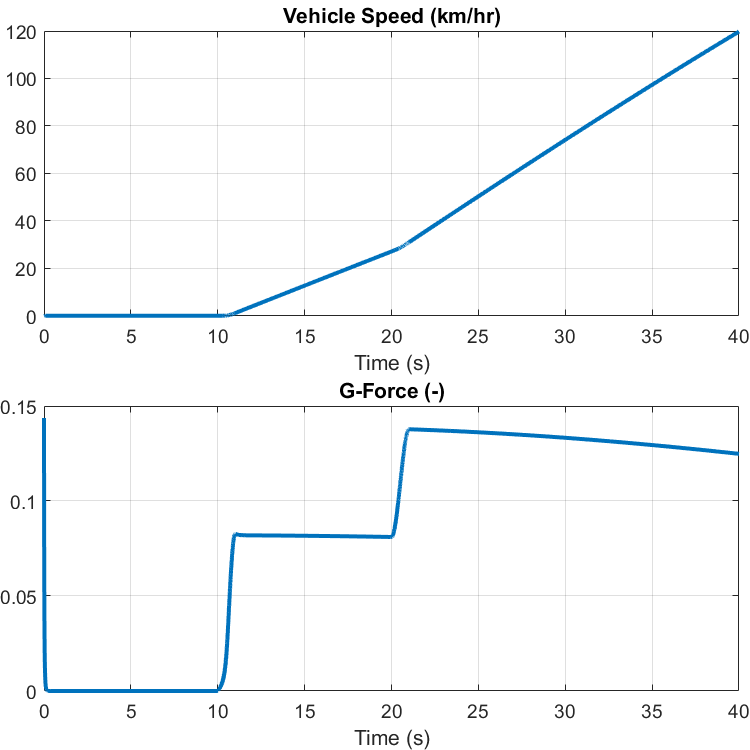

RoadGrade3


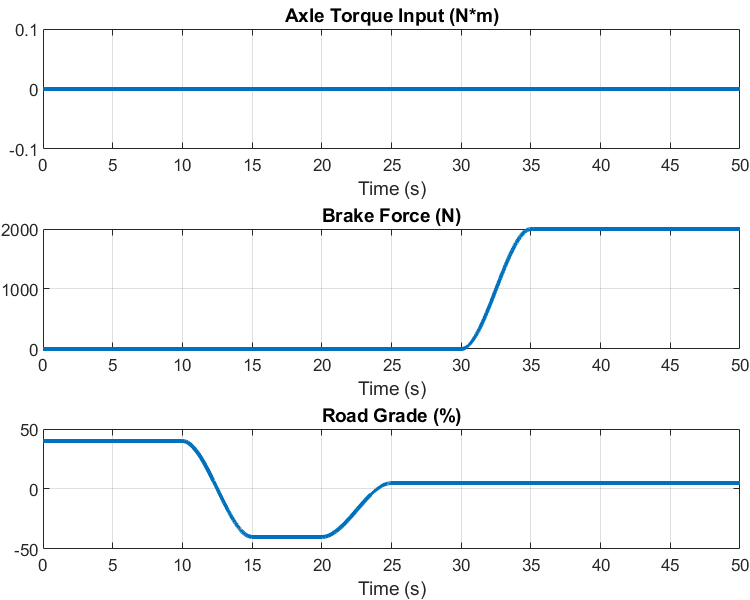

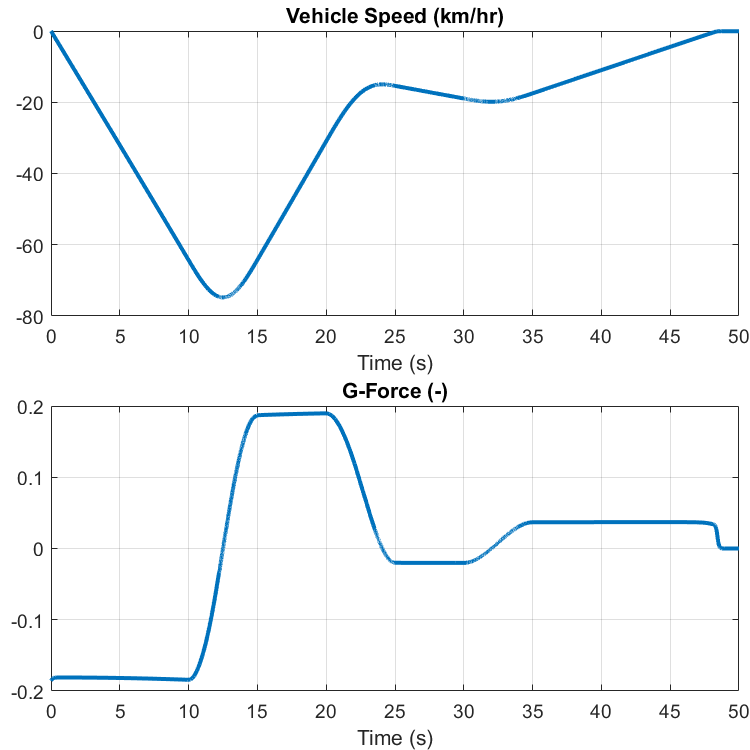

DriveAxle


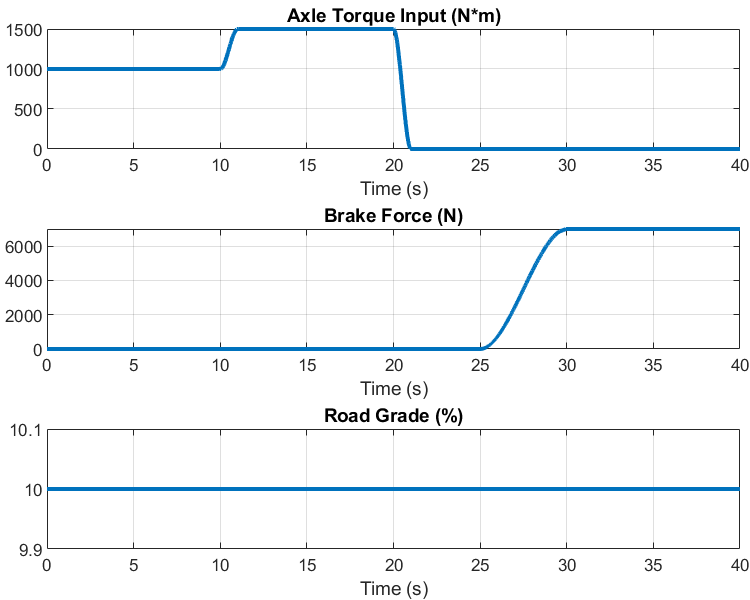

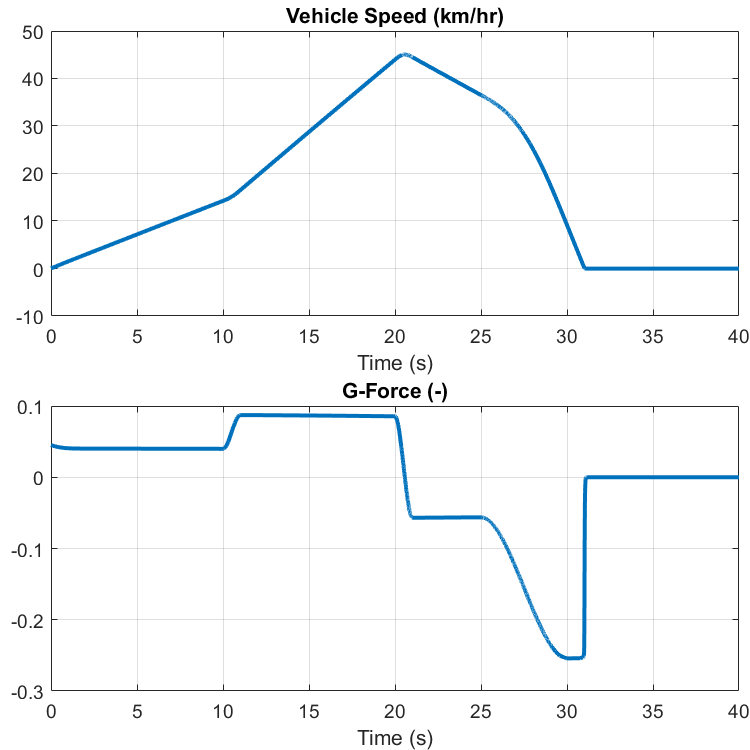

for idx = 1 : numSim
  disp(inputPatterns(idx))
  Vehicle1D_plot_results(simOut(idx).logsout)
end

*Copyright 2020-2022 The Mathworks, Inc.*